# **IPI Solution**

close all
clearvars
clc

skew = @(x) [  0  ,-x(3), x(2);
              x(3),  0  ,-x(1);
             -x(2), x(1),  0 ];

## Symbolic variables

syms q1 q2 real

syms alpha1 a1 d1 real
syms alpha2 a2 d2 real

syms l1 lc1 l2 lc2 h1 delta dq1 dq2 ddq1 ddq2 g real % other parameters are real numbers

syms I1xx I1xy I1xz I1yy I1yz I1zz real
syms I2xx I2xy I2xz I2yy I2yz I2zz real

% Inertial parameters
% Masses
syms m1 m2 positive 

% First moments of mass
syms mX1 mY1 mZ1 real
syms mX2 mY2 mZ2 real

% Inertial matrices
syms XX1 YY1 ZZ1 positive
syms XY1 XZ1 YZ1 real
syms XX2 YY2 ZZ2 positive
syms XY2 XZ2 YZ2 real

assume(I1xx >= 0)
assume(I1yy >= 0)
assume(I1zz >= 0)

assume(I2xx >= 0)
assume(I2yy >= 0)
assume(I2zz >= 0)

syms theta1(t) theta2(t) dtheta1(t) dtheta2(t)

% Inertias defined at the CoM of the links in a frame with the same
% orientation of the joint frame

I1 = [I1xx I1xy I1xz;
      I1xy I1yy I1yz;
      I1xz I1yz I1zz];
  
I2 = [I2xx I2xy I2xz;
      I2xy I2yy I2yz;
      I2xz I2yz I2zz];

% Inertias w.r.t. the joint frame
J1 = [XX1 XY1 XZ1;
      XY1 YY1 YZ1;
      XZ1 YZ1 ZZ1];

J2 = [XX2 XY2 XZ2;
      XY2 YY2 YZ2;
      XZ2 YZ2 ZZ2];

% First moment of mass vectors
s_1 = [mX1 mY1 mZ1]';
s_2 = [mX2 mY2 mZ2]';  
  
% Inertial parameter vectors
X1 = [XX1 XY1 XZ1 YY1 YZ1 ZZ1 mX1 mY1 mZ1 m1]';
X2 = [XX2 XY2 XZ2 YY2 YZ2 ZZ2 mX2 mY2 mZ2 m2]';

% First moment of mass vectors
s_1 = [mX1 mY1 mZ1]';
s_2 = [mX2 mY2 mZ2]';  
  
% Inertial parameter vectors
X1 = [XX1 XY1 XZ1 YY1 YZ1 ZZ1 mX1 mY1 mZ1 m1]';
X2 = [XX2 XY2 XZ2 YY2 YZ2 ZZ2 mX2 mY2 mZ2 m2]';
X  = [X1; X2];

disp(['>> ' 'Symbolic variables defined']);

>> Symbolic variables defined


## Kinematic terms: transformation, rotation and Jacobian matrices

MDH parameters

alpha = [alpha1 alpha2];
a     = [a1 a2];
d     = [d1 d2];

Rotation matrices around x-axis

Rx_alpha1 = [1    0         0   ;
             0  cos(alpha1) -sin(alpha1);
             0  sin(alpha1)  cos(alpha1)];         
Rx_alpha2 = [1    0         0   ;
             0  cos(alpha2) -sin(alpha2);
             0  sin(alpha2)  cos(alpha2)];

Rotation matrices around z-axis

Rz1         = [cos(q1) -sin(q1) 0;
               sin(q1)  cos(q1) 0;
               0           0    1];
Rz2         = [cos(q2), -sin(q2), 0;
               sin(q2),  cos(q2), 0;
                  0   ,     0   , 1];

Rotation matrices between frames

R_0_1 = Rz1;
R_1_2 = Rz2;      
R_0_2 = R_0_1*R_1_2;

Homogeneous transformation matrices

% Pure rotation
T_rot_x_alpha_1 = [[Rx_alpha1;zeros(1,3)],[0;0;0;1]];
% Pure translation
T_trans_x_a_1   = [[eye(3);zeros(1,3)],[a1;0;0;1]];
% Pure rotation
T_rot_z_q_1     = [[Rz1;zeros(1,3)],[0;0;0;1]];
% Pure translation
T_trans_z_a_1   = [[eye(3);zeros(1,3)],[0;0;d1;1]];

% Pure rotation
T_rot_x_alpha_2 = [[Rx_alpha2;zeros(1,3)],[0;0;0;1]];
% Pure translation
T_trans_x_a_2   = [[eye(3);zeros(1,3)],[a2;0;0;1]];
% Pure rotation
T_rot_z_q_2     = [[Rz2;zeros(1,3)],[0;0;0;1]];
% Pure translation
T_trans_z_a_2   = [[eye(3);zeros(1,3)],[0;0;d2;1]];

Transformation matrices between frames (USE the "simplify" command to get easy-to-read outputs)

T_0_1 = simplify(T_rot_x_alpha_1*T_trans_x_a_1*T_rot_z_q_1*T_trans_z_a_1);
T_0_1 = subs(T_0_1,[alpha1 d1 a1],[0 0 0]);
T_1_2 = simplify(T_rot_x_alpha_2*T_trans_x_a_2*T_rot_z_q_2*T_trans_z_a_2);
T_1_2 = subs(T_1_2,[alpha2 d2 a2],[0 0.05 1]);
T_0_2 = simplify(T_0_1*T_1_2);

Centers of mass Jacobians

T_1_1com = [[eye(3);0 0  0],[lc1; 0; 0; 1]];
T_0_1com = T_0_1*T_1_1com;

T_2_2com = [[eye(3);0 0  0],[lc2; 0; 0; 1]];
T_0_2com = simplify(T_0_1*T_1_2*T_2_2com);

T_2_EE = [[eye(3);0 0  0],[l2; 0; 0; 1]];
T_0_EE = simplify(T_0_1*T_1_2*T_2_EE);

p_0_1com = T_0_1com(1:3,4);
p_0_2com = T_0_2com(1:3,4);

J_0_v1com = [diff(p_0_1com) zeros(3,1)];
J_0_w1com = [zeros(2,2);1,0];

J_0_v2com = [diff(p_0_2com,q1), diff(p_0_2com,q2)];
J_0_w2com = [zeros(2,2);1,1];

# TASK 1: Regressor form of the dynamics equations

## In this task the goal is to get a numerical comparison between the robot dynamics from the the first lab experiment, the LIP form and minimal-parameter form.

# TASK 1a

## Get the expressions for the kinetic and potential energies in terms of the inertial parameters

Useful terms

z_vec = [0; 0; 1]; %coordinates of the unitary z-axis vector for all joint frames
R_0_1 = T_0_1(1:3,1:3);
R_1_2 = T_1_2(1:3,1:3);
p_0_1 = T_0_1(1:3,4);  % position vector of origin of CS1 in CS0
p_1_2 = T_1_2(1:3,4);  % position vector of origin of CS2 in CS1

Angular velocities

w_0_0 = [0;0;0];% <<YOUR CODE HERE>>
w_1_1 = R_0_1'*w_0_0+dq1*z_vec;% <<YOUR CODE HERE>>
w_2_2 = R_1_2'*w_1_1+dq2*z_vec;% <<YOUR CODE HERE>>

Linear velocities

v_0_0    = [0;0;0]; % <<YOUR CODE HERE>>
v_1_1    = R_0_1'*(v_0_0+cross(w_0_0,p_0_1)) % <<YOUR CODE HERE>>

$$v\_1\_1 = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

v_1_1com = []; % <<YOUR CODE HERE>>
v_2_2    = R_1_2'*(v_1_1+cross(w_1_1,p_1_2)) % <<YOUR CODE HERE>>

$$v\_2\_2 = \left(\begin{array}{c} {\mathrm{dq}}_{1}\,\sin\left(q_{2}\right)\\ {\mathrm{dq}}_{1}\,\cos\left(q_{2}\right)\\ 0 \end{array}\right)$$

v_2_2com = []; % <<YOUR CODE HERE>>
v_0_2com = []; % <<YOUR CODE HERE>>

disp(['>> ' 'Linear and angular velocities defined']);

>> Linear and angular velocities defined


Kinetic energy $T = T_1+T_2$ (see eq. (2) in the script)

% Symbolic vectors of joint angles and velocities
q  = [q1;q2];
dq = [dq1; dq2];

% Kinetic energy of the individual links
K_1 = 1/2*(w_1_1'*J1*w_1_1+m1*v_1_1'*v_1_1+2*s_1'*cross(v_1_1,w_1_1)); % <<YOUR CODE HERE>>
K_2 = 1/2*(w_2_2'*J2*w_2_2+m2*v_2_2'*v_2_2+2*s_2'*cross(v_2_2,w_2_2)); % <<YOUR CODE HERE>>
K   = simplify(K_1 + K_2)

$$K = \frac{{\mathrm{ZZ}}_{2}\,{\left({\mathrm{dq}}_{1}+{\mathrm{dq}}_{2}\right)}^{2}}{2}+\frac{{\mathrm{ZZ}}_{1}\,{{\mathrm{dq}}_{1}}^{2}}{2}+\frac{{{\mathrm{dq}}_{1}}^{2}\,m_{2}\,{\cos\left(q_{2}\right)}^{2}}{2}+\frac{{{\mathrm{dq}}_{1}}^{2}\,m_{2}\,{\sin\left(q_{2}\right)}^{2}}{2}+{\mathrm{dq}}_{1}\,{\mathrm{mX}}_{2}\,\cos\left(q_{2}\right)\,\left({\mathrm{dq}}_{1}+{\mathrm{dq}}_{2}\right)-{\mathrm{dq}}_{1}\,{\mathrm{mY}}_{2}\,\sin\left(q_{2}\right)\,\left({\mathrm{dq}}_{1}+{\mathrm{dq}}_{2}\right)$$


disp(['>> ' 'Kinetic energy defined']);

>> Kinetic energy defined


Potential energy: $U = U_1+U_2$ (see eq. (3) in the script)

g_vec = [0; -g; 0];
U1    = -g_vec'*(m1*p_0_1+R_0_1*s_1); % <<YOUR CODE HERE>>
U2    = -g_vec'*(m2*(R_0_1*p_1_2)+R_0_1*R_1_2*s_2); % <<YOUR CODE HERE>>
U     = simplify(U1 + U2)

$$U = g\,\left({\mathrm{mY}}_{1}\,\cos\left(q_{1}\right)+{\mathrm{mX}}_{1}\,\sin\left(q_{1}\right)\right)+g\,\left({\mathrm{mY}}_{2}\,\cos\left(q_{1}+q_{2}\right)+{\mathrm{mX}}_{2}\,\sin\left(q_{1}+q_{2}\right)+m_{2}\,\sin\left(q_{1}\right)\right)$$


disp(['>> ' 'Potential energy defined']);

>> Potential energy defined


# TASK 1b

## Form the geometry vectors $\mathbf t$ and $\mathbf u$


k = jacobian(K,X)' % <<YOUR CODE HERE>>

$$k = \left(\begin{array}{c} 0\\ 0\\ 0\\ 0\\ 0\\ \frac{{{\mathrm{dq}}_{1}}^{2}}{2}\\ 0\\ 0\\ 0\\ 0\\ 0\\ 0\\ 0\\ 0\\ 0\\ \frac{{\left({\mathrm{dq}}_{1}+{\mathrm{dq}}_{2}\right)}^{2}}{2}\\ {\mathrm{dq}}_{1}\,\cos\left(q_{2}\right)\,\left({\mathrm{dq}}_{1}+{\mathrm{dq}}_{2}\right)\\ -{\mathrm{dq}}_{1}\,\sin\left(q_{2}\right)\,\left({\mathrm{dq}}_{1}+{\mathrm{dq}}_{2}\right)\\ 0\\ \frac{{{\mathrm{dq}}_{1}}^{2}\,{\cos\left(q_{2}\right)}^{2}}{2}+\frac{{{\mathrm{dq}}_{1}}^{2}\,{\sin\left(q_{2}\right)}^{2}}{2} \end{array}\right)$$

u = jacobian(U,X)' % <<YOUR CODE HERE>>

$$u = \left(\begin{array}{c} 0\\ 0\\ 0\\ 0\\ 0\\ 0\\ g\,\sin\left(q_{1}\right)\\ g\,\cos\left(q_{1}\right)\\ 0\\ 0\\ 0\\ 0\\ 0\\ 0\\ 0\\ 0\\ g\,\sin\left(q_{1}+q_{2}\right)\\ g\,\cos\left(q_{1}+q_{2}\right)\\ 0\\ g\,\sin\left(q_{1}\right) \end{array}\right)$$

# TASK 1c

## Use the Lagrangian equations (17) to construct the regressor matrix $\mathbf{C}$

Lagrangian

l = k-u % <<YOUR CODE HERE>>

$$l = \left(\begin{array}{c} 0\\ 0\\ 0\\ 0\\ 0\\ \frac{{{\mathrm{dq}}_{1}}^{2}}{2}\\ -g\,\sin\left(q_{1}\right)\\ -g\,\cos\left(q_{1}\right)\\ 0\\ 0\\ 0\\ 0\\ 0\\ 0\\ 0\\ \frac{{\left({\mathrm{dq}}_{1}+{\mathrm{dq}}_{2}\right)}^{2}}{2}\\ {\mathrm{dq}}_{1}\,\cos\left(q_{2}\right)\,\left({\mathrm{dq}}_{1}+{\mathrm{dq}}_{2}\right)-g\,\sin\left(q_{1}+q_{2}\right)\\ -g\,\cos\left(q_{1}+q_{2}\right)-{\mathrm{dq}}_{1}\,\sin\left(q_{2}\right)\,\left({\mathrm{dq}}_{1}+{\mathrm{dq}}_{2}\right)\\ 0\\ \frac{{{\mathrm{dq}}_{1}}^{2}\,{\cos\left(q_{2}\right)}^{2}}{2}+\frac{{{\mathrm{dq}}_{1}}^{2}\,{\sin\left(q_{2}\right)}^{2}}{2}-g\,\sin\left(q_{1}\right) \end{array}\right)$$

Regressor matrix

clear C

N = 2; % Number of joints

disp(['>> ' 'Calculating regressor matrix...']);

>> Calculating regressor matrix...



dldq=jacobian(l,q);
dlddq=jacobian(l,dq);
dlddq=subs(dlddq,[q;dq],[theta1(t);theta2(t);dtheta1(t);dtheta2(t)]);
dtdlddq=diff(dlddq,t);
dtdlddq=subs(dtdlddq,[diff(theta1(t),t),diff(theta2(t),t),diff(dtheta1(t),t),diff(dtheta2(t),t),dtheta1,dtheta2,theta1,theta2], ...
    [dq1,dq2,ddq1,ddq2,dq1,dq2,q1,q2]);
C=simplify((dtdlddq-dldq))'

$$C = \begin{array}{l} \left(\begin{array}{cccccccccccccccccccc} 0 & 0 & 0 & 0 & 0 & {\mathrm{ddq}}_{1} & g\,\cos\left(q_{1}\right) & -g\,\sin\left(q_{1}\right) & 0 & 0 & 0 & 0 & 0 & 0 & 0 & {\mathrm{ddq}}_{1}+{\mathrm{ddq}}_{2} & -\sin\left(q_{2}\right)\,{{\mathrm{dq}}_{2}}^{2}-2\,{\mathrm{dq}}_{1}\,\sin\left(q_{2}\right)\,{\mathrm{dq}}_{2}+\sigma_{2}+2\,{\mathrm{ddq}}_{1}\,\cos\left(q_{2}\right)+{\mathrm{ddq}}_{2}\,\cos\left(q_{2}\right) & -\cos\left(q_{2}\right)\,{{\mathrm{dq}}_{2}}^{2}-2\,{\mathrm{dq}}_{1}\,\cos\left(q_{2}\right)\,{\mathrm{dq}}_{2}-\sigma_{1}-2\,{\mathrm{ddq}}_{1}\,\sin\left(q_{2}\right)-{\mathrm{ddq}}_{2}\,\sin\left(q_{2}\right) & 0 & {\mathrm{ddq}}_{1}+g\,\cos\left(q_{1}\right)\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & {\mathrm{ddq}}_{1}+{\mathrm{ddq}}_{2} & \sin\left(q_{2}\right)\,{{\mathrm{dq}}_{1}}^{2}+\sigma_{2}+{\mathrm{ddq}}_{1}\,\cos\left(q_{2}\right) & \cos\left(q_{2}\right)\,{{\mathrm{dq}}_{1}}^{2}-\sigma_{1}-{\mathrm{ddq}}_{1}\,\sin\left(q_{2}\right) & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=g\,\sin\left(q_{1}+q_{2}\right)\\ \sigma_{2}=g\,\cos\left(q_{1}+q_{2}\right) \end{array}$$


disp(['>> ' 'Regressor matrix defined']);

>> Regressor matrix defined


# TASK 1d

## Recursive computation of the minimal-parameters

Use eq. (20) to get the regrouped parameters.

XX_2p = XX2-YY2;
XX_1p = XX1+YY2+2*d2*mZ2+d2^2*m2;
XY_1p = XY1+a2*sin(alpha2)*mZ2+a2*d2*sin(alpha2)*m2;
XZ_1p = XZ1-a2*cos(alpha2)*mZ2-a2*d2*cos(alpha2)*m2;
YY_1p = YY1+(cos(alpha2))^2*YY2+2*d2*(cos(alpha2))^2*mZ2+(a2^2+d2^2*(cos(alpha2))^2)*m2;
YZ_1p = YZ1+cos(alpha2)*sin(alpha2)*YY2+2*d2*cos(alpha2)*sin(alpha2)*mZ2+d2^2*cos(alpha2)*sin(alpha2)*m2;
ZZ_1p = ZZ1+sin(alpha2)^2*YY2+2*d2*sin(alpha2)^2*mZ2+(a2^2+d2^2*(sin(alpha2))^2)*m2;
mX_1p = mX1+a2*m2;
mY_1p = mY1-sin(alpha2)*mZ2-d2*sin(alpha2)*m2;
mZ_1p = mZ1+cos(alpha2)*mZ2+d2*cos(alpha2)*m2;
m_1p = m1+m2;


X_p = [XX_1p XY_1p XZ_1p YY_1p YZ_1p ZZ_1p mX_1p mY_1p mZ_1p m_1p XX_2p XY2 XZ2 YY2 YZ2 ZZ2 mX2 mY2 mZ2 m2]

$$X\_p = \left(\begin{array}{cccccccccccccccccccc} m_{2}\,{d_{2}}^{2}+2\,{\mathrm{mZ}}_{2}\,d_{2}+{\mathrm{XX}}_{1}+{\mathrm{YY}}_{2} & {\mathrm{XY}}_{1}+a_{2}\,{\mathrm{mZ}}_{2}\,\sin\left(\alpha_{2}\right)+a_{2}\,d_{2}\,m_{2}\,\sin\left(\alpha_{2}\right) & {\mathrm{XZ}}_{1}-a_{2}\,{\mathrm{mZ}}_{2}\,\cos\left(\alpha_{2}\right)-a_{2}\,d_{2}\,m_{2}\,\cos\left(\alpha_{2}\right) & {\mathrm{YY}}_{1}+m_{2}\,\left({a_{2}}^{2}+{d_{2}}^{2}\,{\cos\left(\alpha_{2}\right)}^{2}\right)+{\mathrm{YY}}_{2}\,{\cos\left(\alpha_{2}\right)}^{2}+2\,d_{2}\,{\mathrm{mZ}}_{2}\,{\cos\left(\alpha_{2}\right)}^{2} & m_{2}\,\cos\left(\alpha_{2}\right)\,\sin\left(\alpha_{2}\right)\,{d_{2}}^{2}+2\,{\mathrm{mZ}}_{2}\,\cos\left(\alpha_{2}\right)\,\sin\left(\alpha_{2}\right)\,d_{2}+{\mathrm{YZ}}_{1}+{\mathrm{YY}}_{2}\,\cos\left(\alpha_{2}\right)\,\sin\left(\alpha_{2}\right) & {\mathrm{ZZ}}_{1}+m_{2}\,\left({a_{2}}^{2}+{d_{2}}^{2}\,{\sin\left(\alpha_{2}\right)}^{2}\right)+{\mathrm{YY}}_{2}\,{\sin\left(\alpha_{2}\right)}^{2}+2\,d_{2}\,{\mathrm{mZ}}_{2}\,{\sin\left(\alpha_{2}\right)}^{2} & {\mathrm{mX}}_{1}+a_{2}\,m_{2} & {\mathrm{mY}}_{1}-{\mathrm{mZ}}_{2}\,\sin\left(\alpha_{2}\right)-d_{2}\,m_{2}\,\sin\left(\alpha_{2}\right) & {\mathrm{mZ}}_{1}+{\mathrm{mZ}}_{2}\,\cos\left(\alpha_{2}\right)+d_{2}\,m_{2}\,\cos\left(\alpha_{2}\right) & m_{1}+m_{2} & {\mathrm{XX}}_{2}-{\mathrm{YY}}_{2} & {\mathrm{XY}}_{2} & {\mathrm{XZ}}_{2} & {\mathrm{YY}}_{2} & {\mathrm{YZ}}_{2} & {\mathrm{ZZ}}_{2} & {\mathrm{mX}}_{2} & {\mathrm{mY}}_{2} & {\mathrm{mZ}}_{2} & m_{2} \end{array}\right)$$

disp(['>> ' 'Parameters regrouped']);

>> Parameters regrouped


# TASK 1e

## Parameters without influence on the dynamics

Indeces of the elements that have no influence on the dynamics

index = [1,2,3,4,5,9,10,11,12,13,14,15,19,20]; % <<YOUR CODE HERE>>

Reduced regressor matrix


beta_b=X_p;
beta_b(index)=[];
C_b=C;
C_b(:,index) = []; % <<YOUR CODE HERE>> 

Minimal-parameter vector

%beta_b(index) = []; % <<YOUR CODE HERE>> 

disp(['>> ' 'Reduced regressor matrix defined']);

>> Reduced regressor matrix defined


disp(['>> ' 'Minimal-parameter vector defined']);

>> Minimal-parameter vector defined


# TASK 1f

## Create a Simulink model to test your findings

Assign values to symbolic variables

m1    = 10;
m2    = 10;
l1    = 1; 
lc1   = l1/2 ;
l2    = 1;
lc2   = l2/2;
h1    = 0.1;
delta = 0.05;
g     = 9.81;

Compute the expressions for the inertia tensors w.r.t. the links' center of mass

I_com1 = diag([1/12*m1*(h1^2 + h1^2), 1/12*m1*(l1^2 + h1^2), 1/12*m1*(l1^2 + h1^2)]); 
I_com2 = diag([1/12*m2*(h1^2 + h1^2), 1/12*m2*(l2^2 + h1^2), 1/12*m2*(l2^2 + h1^2)]);

Compute the expressions for the inertia tensors w.r.t. the links' frames

J1 = I_com1 - m1*skew([lc1 0 0])*skew([lc1 0 0]);
J2 = I_com2 - m2*skew([lc2 0 0])*skew([lc2 0 0]);

[I1xx, I1xy, I1xz, I1yy, I1yz, I1zz] = deal(I_com1(1,1),I_com1(1,2),I_com1(1,3),I_com1(2,2),I_com1(2,3),I_com1(3,3));
[I2xx, I2xy, I2xz, I2yy, I2yz, I2zz] = deal(I_com2(1,1),I_com2(1,2),I_com2(1,3),I_com2(2,2),I_com2(2,3),I_com2(3,3));

[XX1, XY1, XZ1, YY1, YZ1, ZZ1] = deal(J1(1,1),J1(1,2),J1(1,3),J1(2,2),J1(2,3),J1(3,3));
[XX2, XY2, XZ2, YY2, YZ2, ZZ2] = deal(J2(1,1),J2(1,2),J2(1,3),J2(2,2),J2(2,3),J2(3,3));

First moments of mass

mX1 = m1*lc1;
mY1 = 0;
mZ1 = 0;
mX2 = m2*lc2;
mY2 = 0;
mZ2 = 0;

MDH parameters

a1     = 0;
a2     = l1;
alpha1 = 0;
alpha2 = 0;
d1     = 0;
d2     = delta;

Numerical value of the (full) inertial prameters vector

X = double(subs([X1;X2]))

X =     0.0167
         0
         0
    3.3417
         0
    3.3417
    5.0000
         0
         0
   10.0000


beta_b = double(subs(beta_b))

beta_b =    13.3417   15.0000         0    3.3417    5.0000         0




disp(['>> ' 'Assigned numerical values to symbolic variables']);

>> Assigned numerical values to symbolic variables


The code below will generate Simulink function blocks **based on your expressions **for the regressor matrices as well as for the parameter vectors.. The regressor matrix blocks will depend only on the joint position, velocity, and/or acceleration.

% new_system('my_system')
% open_system('my_system')
% 
% matlabFunctionBlock('my_system/reg_C', subs(C),'Outputs', {'C'})
% matlabFunctionBlock('my_system/reg_Cb', subs(C_b),'Outputs', {'Cb'})

# TASK 2: Trajectory optimization

## In this task, optimal trajectories are created, which will later be used in the virtual identification experiment

# TASK 2a

open('RMIC_calc_fourier_traj_poly.m')

# TASK 2b

open('RMIC_calc_fourier_traj_poly.m')

#  TASK 2c

open('RMIC_calc_fourier_traj_poly.m')

#  TASK 2d

open('RMIC_arm_inf_matrix.m')

#   TASK 2f

open('RMIC_arm_inf_matrix.m')

Start the trajectory optimization by running the script 'RMIC_traj_optim_config_start.m'

>> constPar structure created
>> Parameters loaded
>> Joint angle constraints
     q_min      q_c0      q_max
   -6.2832         0    6.2832
   -6.2832         0    6.2832

    3.9549
    5.0993
   -4.6874
    5.1946
    1.6633
   -5.0575
   -2.7835
    0.5891
    5.7492
    5.8420



*******************************************************************
*                   TRAJECTORY OPTIMIZATION                       *
*******************************************************************
  1×3 table

    n_cosines    n_samples    t_end
    _________    _________    _____

        5          30000       30  



                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      11    4.273120e+03    3.037e+01    9.706e+02
    1      23    3.505161e+03    5.320e+01    1.511e+03    1.405e+01
    2      35    1.564322e+03    2.562e+01    1.642e+03    8.856e+00
    3      46    9.444005e+02    3.770e+01    7.264e+02    1.915e+01
    4      57    9.227723e+02    3.749e+01    5.887e+02    5.816e-01
    5      68    8.980816e+02    3.728e+01    4.837e+02    1.050e+01
    6      82    8.207981e+02    3.429e+01    5.200e+02    4.764e+00
    7      96    8.010525e+02    3.202e+01    6.275e+02    4.229e+00
    8     111    9.608716e+02    1.534e+01    1.806e+02    7.694e+00
    9     130    2.053201e+03    9.082e+00    6.931e+02    3.376e+00
   10     145    9.560622e+02    2.497e+00    3.420e+02    6.842e+00
   11     166    1.062919e+03    1.594e+00    5.203e+02    1.656e+00
   12     178    1.067365e+03    1.535e+00    8

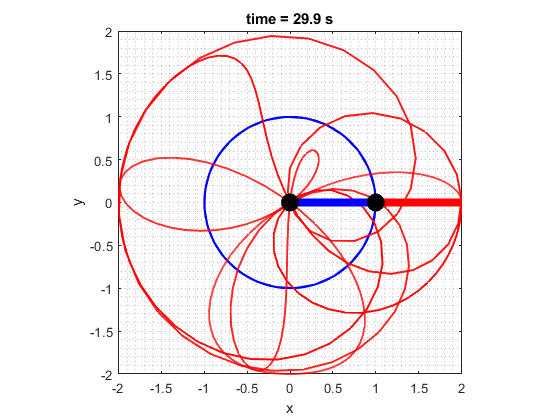

>> Finished trajectory animation
>> Showing trajectory plots


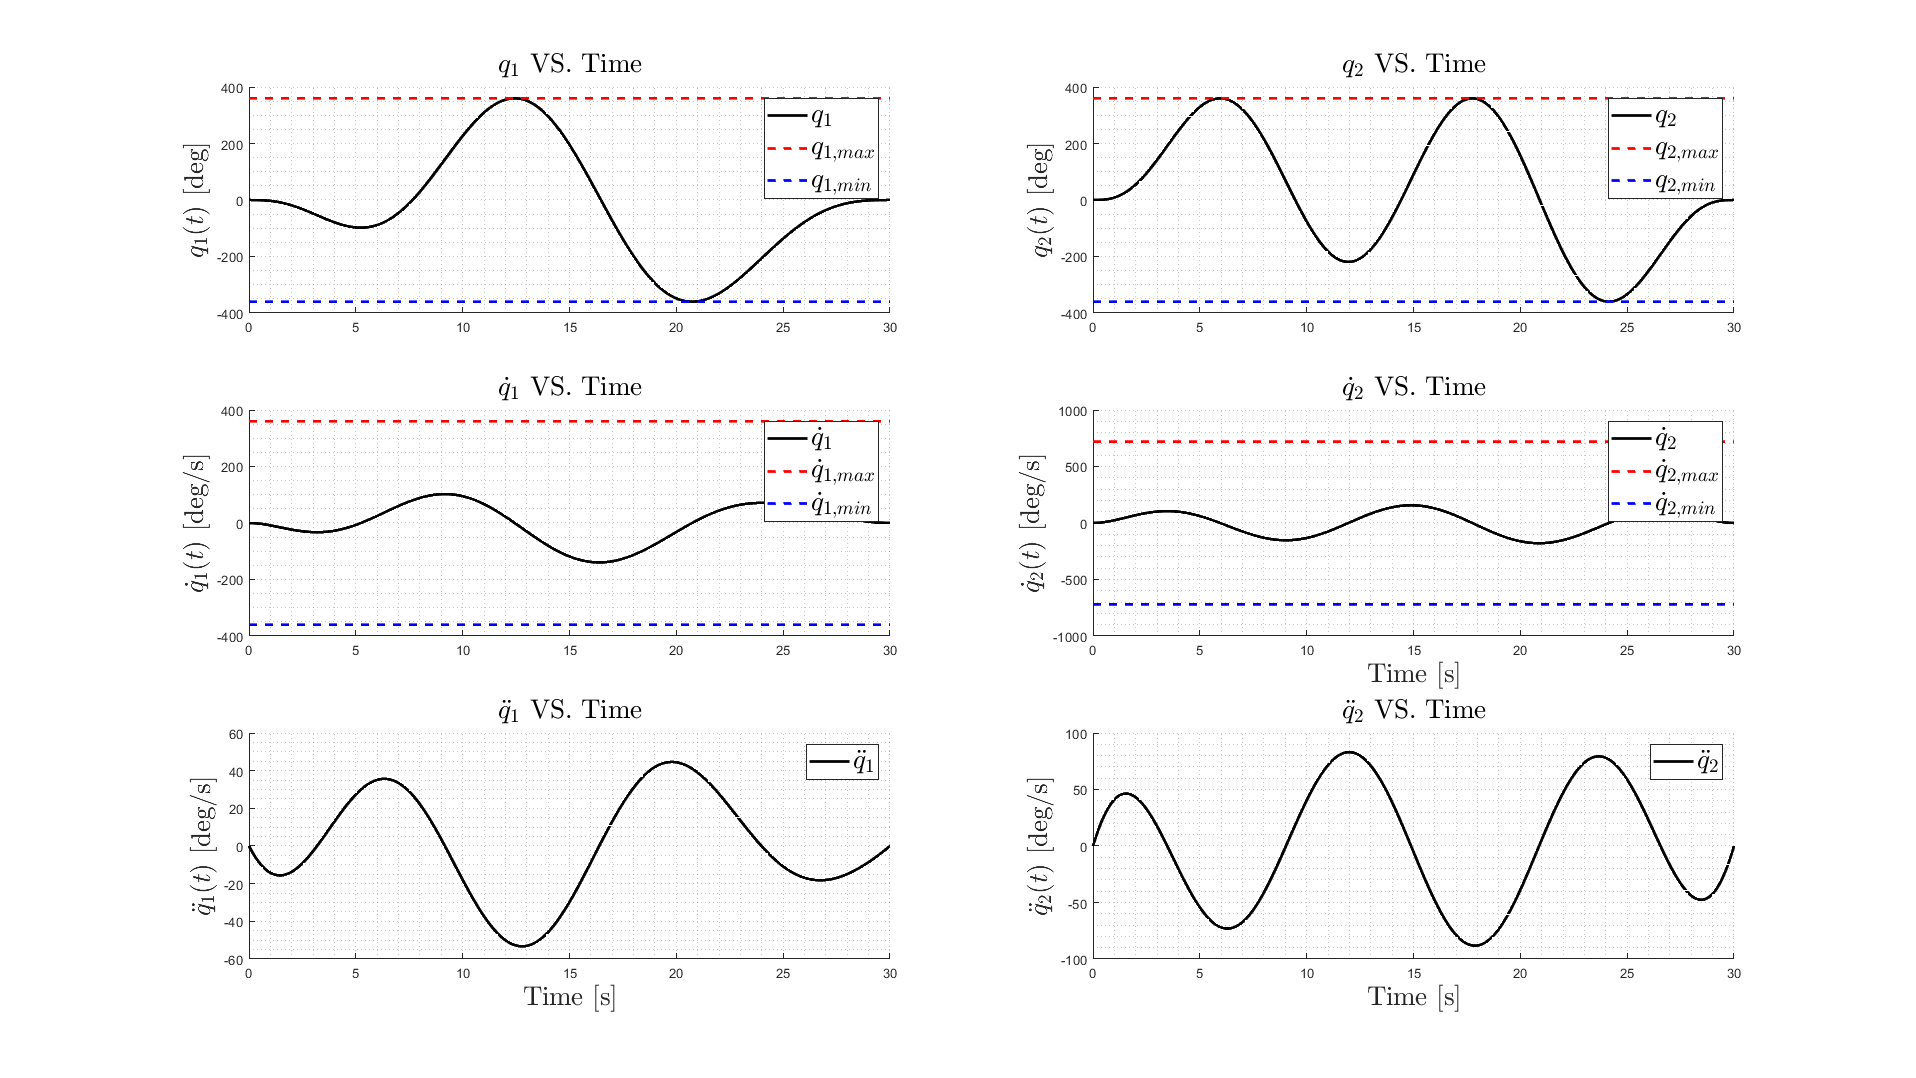

>> Trajectory parameters stored
>> Fourier polynomial defined


run('RMIC_traj_optim_config_start.m')

# TASK 3: Parameter identification

## A virtual identification experiment is executed. With the collected measurement data (joint positions, velocities and accelerations as well as joint torques), the minimal parameters of the planar manipulator will be estimated.

Initialization

close all
T_smp      = 1E-3;
seed       = 0;
q_dist_var = (pi*0.005/2)^2 ;

Check in trajectory optimal parameters exist

if(~isfield(constPar,'a_opt'))
    warning('Trajectory parameters not available. Does <constPar.a_opt> have values?')
end

Open and configure model

sl_Modellname = 'RMIC_ident_experiment';
load_system(sl_Modellname)
open_system(sl_Modellname)
configSet = getActiveConfigSet(sl_Modellname);
set_param(configSet, 'Solver', 'ode4');
set_param(configSet, 'FixedStep', '1e-3');

# TASK 3a

## Run the Simulink model 'RMIC_ident_experiment' to collect data.

The structure array 'sl' constains the required measurements, you can type the name of the variable in the command window to see its contents

**NOTE:** remember to find a way to deal with the measurement noise

constPar.test_trajectory = 0;

simOut      = sim(sl_Modellname, 'StopTime', '30'); 
sl          = get_simulink_outputs(simOut, sl_Modellname);
% <<YOUR CODE HERE>>

# TASK 3b

## Identification

Set the information matrix and information vector based on the measurements collected above.

% <<YOUR CODE HERE>>

# TASK 3c

## Torque reproduction based on found minimal-parameters

**IMPORTANT: DO NOT change the code in this section!!!**

figure

tau_hat = reshape(F_mat*beta_b_hat,constPar.noj,points); 

close all

for i=1:constPar.noj
    subplot(2,1,i)
    hold on
    title('Joint torque VS. Time')
    plot(sl.t,tau_m(:,i),'b','LineWidth',3)
    plot(sl.t(1:100:end),tau_hat(i,1:100:end),'r--','LineWidth',3)
    ylabel(strcat('$\tau_',num2str(i),'(t)$ [Nm]'),'FontSize',20,'interpreter','latex')
    legend('Measured','Estimated')
    grid minor
end
xlabel('Time [s]','FontSize',20)

# TASK 3d

## Test with a second trajectory

constPar.test_trajectory = 1;
lambdas = RMIC_get_fourier_lambdas(constPar.a_test, constPar.noj, constPar.nop, constPar.tend, constPar.omega, constPar.q_bound, constPar);
simOut  = sim(sl_Modellname, 'StopTime', '30'); 
sl      = get_simulink_outputs(simOut, sl_Modellname);
q       = sl.q_ref;
qD      = sl.dq_ref;
qDD     = sl.ddq_ref;
tau     = sl.tau_m;
points  = size(q_sim,1);
tau_hat = reshape(RMIC_arm_inf_matrix(q, qD, qDD, points, constPar)*beta_b_hat,constPar.noj,points); 

close all
figure
for i=1:constPar.noj
    subplot(2,1,i)
    hold on
    title('Joint torque VS. Time')
    plot(sl.t,tau(:,i),'b','LineWidth',3)
    plot(sl.t(1:100:end),tau_hat(i,1:100:end),'r--','LineWidth',3)
    ylabel(strcat('$\tau_',num2str(i),'(t)$ [Nm]'),'FontSize',20,'interpreter','latex')
    legend('Measured','Estimated')
    grid minor
end
xlabel('Time [s]','FontSize',20)